# Exercise 1

## 1.1

% Initialize variables
A = [0 1; -10 -7];
B = [0; 1];
S = [20 0; 0 20];
Q = [5 0; 0 1];
R = 0.25;

% Apply Finite Cont. Time
del = 0.001;
ind = 5/del;
P_Arr = [];
P_Arr(ind, :) = [20, 0, 0, 20];

for i = (ind-1):-1:1
    P = [P_Arr(i+1,1), P_Arr(i+1,2); P_Arr(i+1,3), P_Arr(i+1,4)];
    P_next = -del.* (P * B * inv(R) * B' * P - Q - P * A - A' * P) + P;
    P_Arr(i,:) = [P_next(1,1), P_next(1,2), P_next(2,1), P_next(2,2)];
end

xVals =      1
     1


A0 =     1.0000    0.0010
   -0.0100    0.9930


B0 = 	1.0e+-3 *

    0.0005
    0.9965


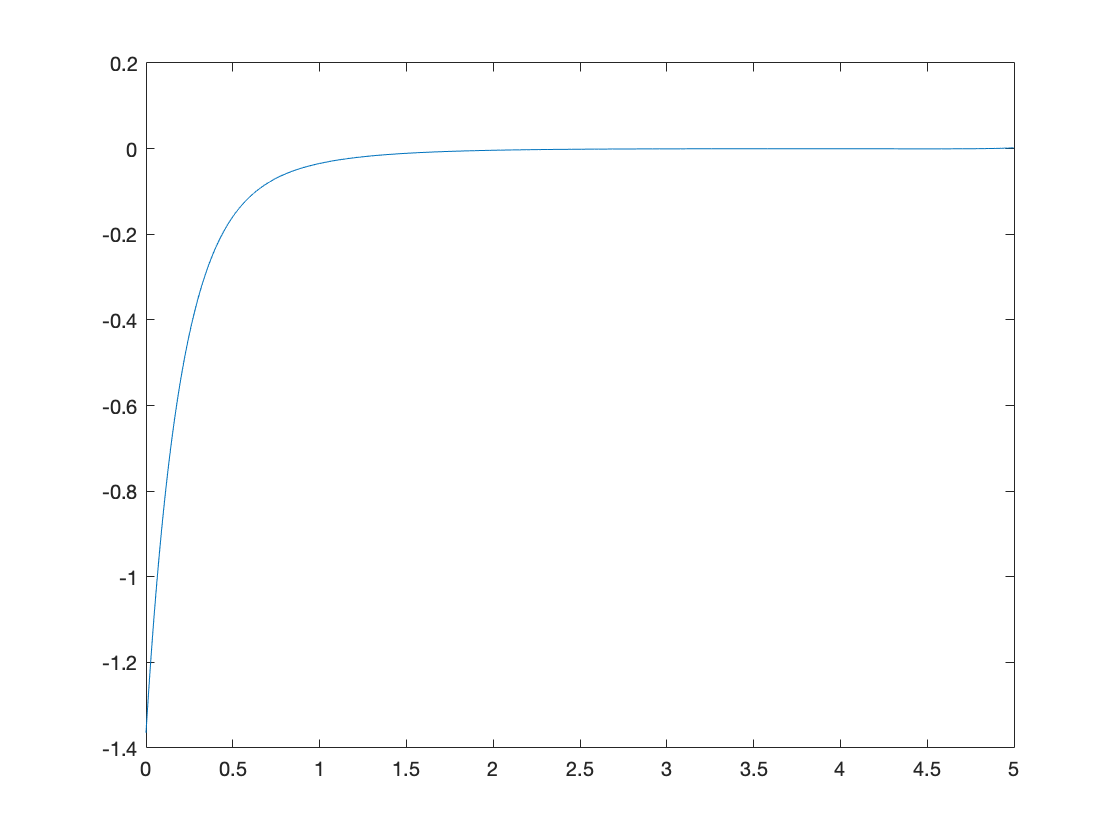

% Apply Discrete Time Model
xVals = [];
xVals(:,1) = [1;1]
u = [];

[M, Ahat] = eig(A);
A0 = M * [exp(del * Ahat(1,1)), 0;
     0, exp(del*Ahat(2,2))]*inv(M)

B0 = inv(A)*(A0-eye(2))*B

for i = 1:ind
    u(i) = -inv(R) * B' * [P_Arr(i,1), P_Arr(i,2); P_Arr(i,3), P_Arr(i,4)]*xVals(:,i);
    xVals(:,i+1) = A0 * xVals(:,i) + B0*u(i);
end

plot([0:del:5-del], u');

## 1.2

% ZOH discretization
del2 = 0.005;
ind2 = 1000;

[M, Ahat] = eig(A);
Adisc = M * [exp(del2 * Ahat(1,1)), 0;
     0, exp(del2*Ahat(2,2))]*inv(M)

Adisc =     0.9999    0.0049
   -0.0491    0.9655



Bdisc = inv(A)*(Adisc-eye(2))*B

Bdisc =     0.0000
    0.0049


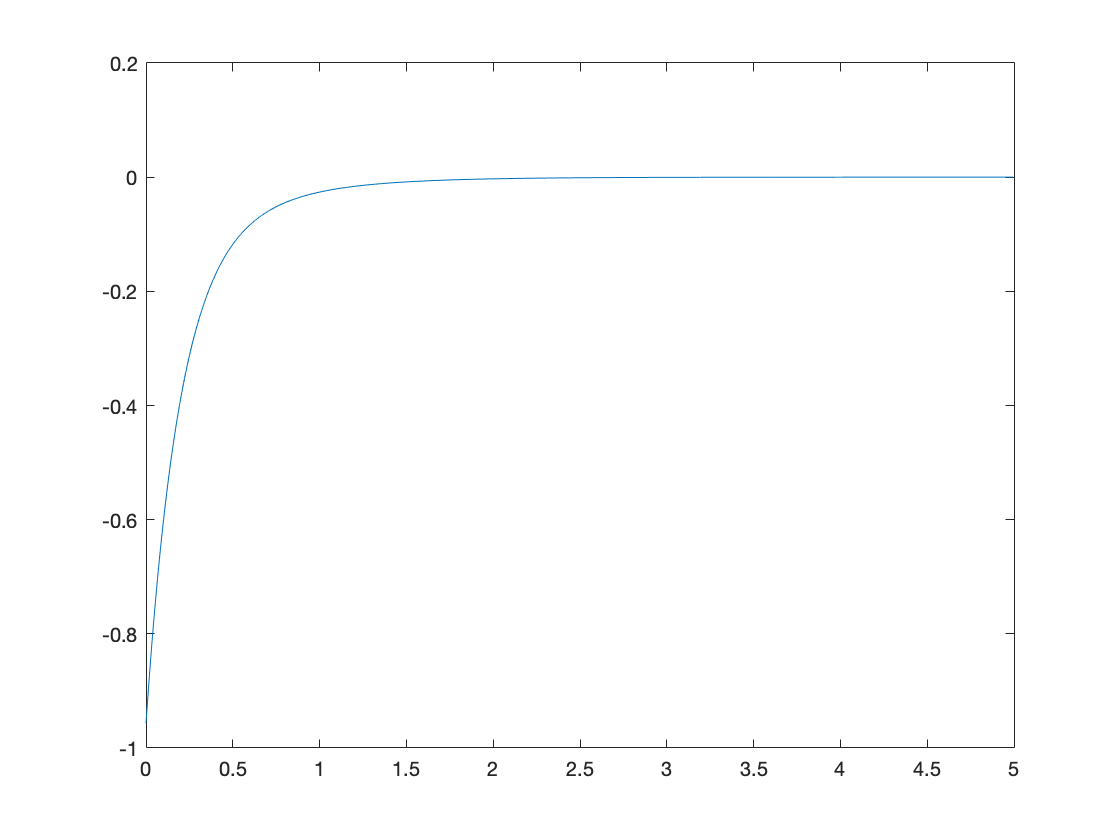

% Apply Finite DT
K = [];
for i = ind2:-1:1
    K(i,:) = inv(R + Bdisc' * S * B) * Bdisc' * S * Adisc;
    S = (Adisc - Bdisc * K(i,:))' * S * (Adisc - Bdisc * K(i,:)) + Q + K(i,:)' * R * K(i,:);
end
xdisc = [];
xdisc(:,1) = [1;1];
udisc = [];

for i = 1:ind2
    udisc(i) = -K(i,:)*xdisc(:,i);
    xdisc(:,i+1) = Adisc * xdisc(:,i) + Bdisc * udisc(i);
end

plot([0:del2:5-del2], udisc')

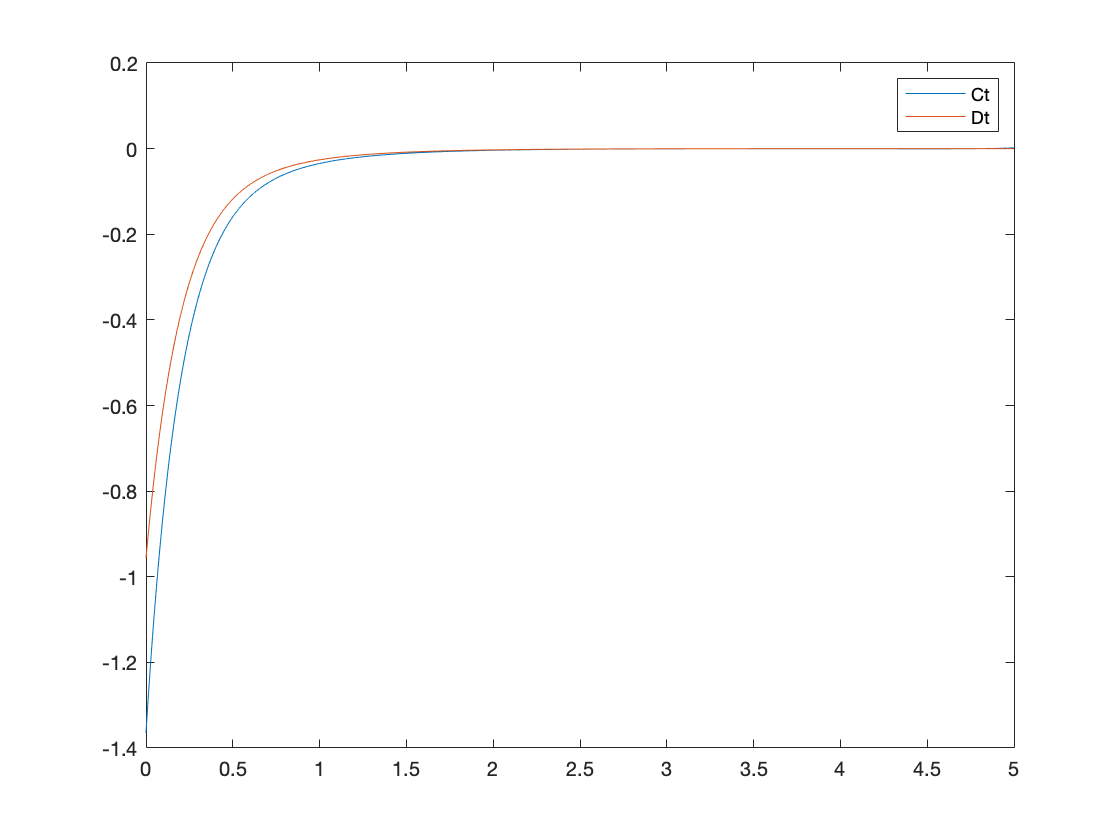

% Comparison of cont. and disc. plots
plot([0:del:5-del], u');
hold on;
plot([0:del2:5-del2], udisc');
hold off;
legend("Ct", "Dt")

CT is applying stronger input than DT, and after 2 seconds, both CT and DT control sequences are similar.

## 1.3

% Apply Inf Time LQR
K_lqr = lqr(A,B,Q,R);
tspan = 0:0.01:5;
uinf = zeros(size(tspan));
xInit = [1;1];
x = lsim(A-B*K_lqr,B,[1,0;0,1],0,uinf,tspan,xInit);

x =     1.0000    1.0000
    1.0091    0.8225
    1.0165    0.6568
    1.0223    0.5022
    1.0266    0.3582
    1.0295    0.2240
    1.0311    0.0993
    1.0315   -0.0167
    1.0308   -0.1244
    1.0290   -0.2243


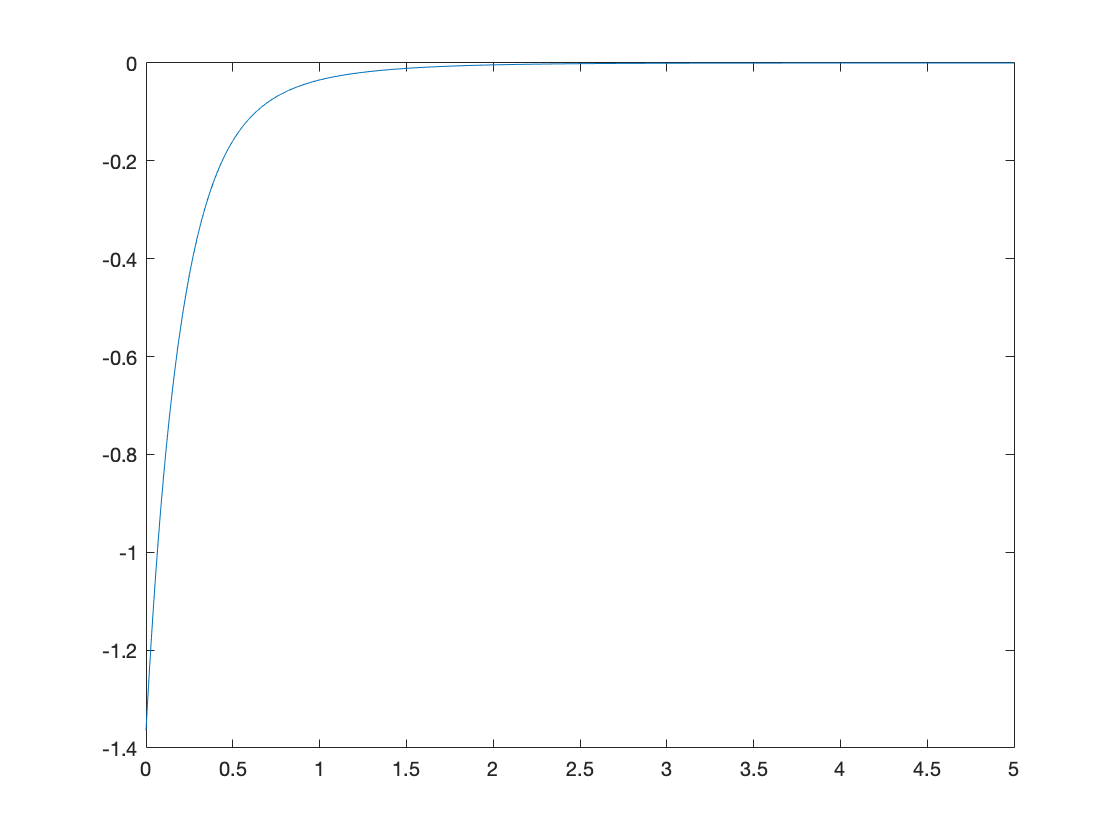

% Plot results
plot(tspan, (-K_lqr*x')');

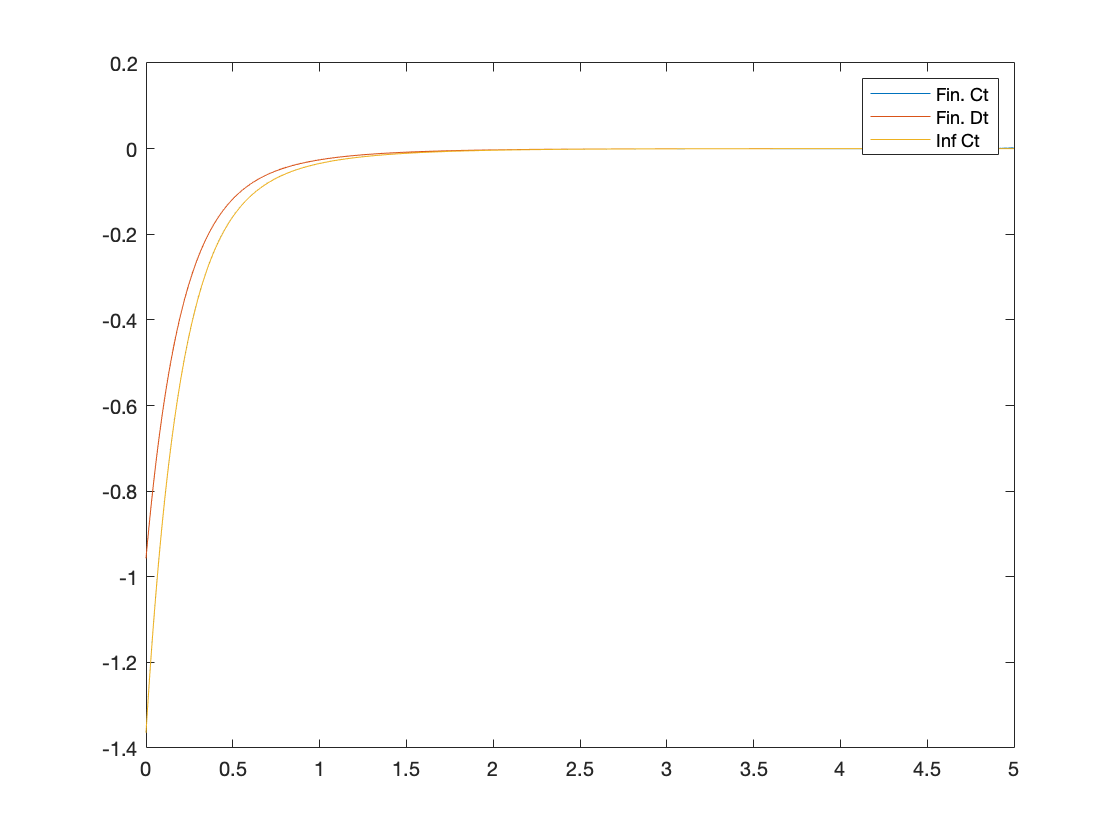

% Compare all results
plot([0:del:5-del], u');
hold on;
plot([0:del2:5-del2], udisc');
hold on;
plot(tspan, (-K_lqr*x')');
hold off;
legend("Fin. Ct", "Fin. Dt", "Inf Ct")

Should see similar results bewteen inf CT curve and finite CT curve. Both of the prior mentioned control sequences apply harder input compared to finite DT within the first 2 seconds.

# Exercise 2

Tuning process should be clear and make logical sense. Relationship between reasoning and appropriate tuning adjustment should be correct.

# Exercise 3

Look for validity within graphs